rrAppPath = "C:\Program Files\RoadRunner R2023b\bin\win64";
s = settings;
s.roadrunner.application.InstallationFolder.TemporaryValue = rrAppPath;
rrProj = "C:\Users\colli\Documents\College\MEEN 401 909 Intro to Mech Engr Design\Simulation\Test\Test";

rrApp=roadrunner(rrProj);
%rrApp=roadrunner(rrProj,NoDisplay=false);

openScenario(rrApp,"LeadCutIn3.rrscenario");

rrSim = rrApp.createSimulation

Connection status: 1
Connected to RoadRunner Scenario server on localhost:50400, with client id {c761563e-e9f1-4b63-9d53-573fb1891c16}


rrSim =   ScenarioSimulation with no properties.


hdMap = getMap(rrSim);
lanes = hdMap.map.lanes;


%set(rrSim,"SimulationCommand","Start");
%while strcmp(get(rrSim,"SimulationStatus"),"Running")
%    pause(1);
%end

%rrLog = get(rrSim,"SimulationLog");

%poseActor1 = rrLog.get('Pose','ActorID',1);
%positionActor1_x = arrayfun(@(x) x.Pose(1,4),poseActor1);
%positionActor1_y = arrayfun(@(x) x.Pose(2,4),poseActor1);
%plot(positionActor1_x,positionActor1_y,"r","LineWidth",2)
%
%poseActor2 = rrLog.get('Pose','ActorID',2);
%positionActor2_x = arrayfun(@(x) x.Pose(1,4),poseActor2);
%positionActor2_y = arrayfun(@(x) x.Pose(2,4),poseActor2);
%plot(positionActor2_x,positionActor2_y,"b","LineWidth",2)
%
%title("Agent Positions from RoadRunner Scenario")
%ylabel("Y (m)")
%xlabel("X (m)")

[nodeTable,edgeTable] = helperGetNodesEdges;

graph = navGraph(nodeTable,edgeTable);
%show(graph)

numLanes = height(nodeTable);
% Select random starting node
astart = randi([1 numLanes],1,1);
numLaneNodesStart = height(nodeTable.LanesStruct(astart).Geometry);
bstart = randi([1 numLaneNodesStart],1,1);
xpointstart = nodeTable.LanesStruct(astart).Geometry(bstart,1)

xpointstart = -35.8548

ypointstart = nodeTable.LanesStruct(astart).Geometry(bstart,2)

ypointstart = 44.8619

zpointstart = nodeTable.LanesStruct(astart).Geometry(bstart,3)

zpointstart = 234.6050

start = [xpointstart,ypointstart,zpointstart]

start =   -35.8548   44.8619  234.6050


% Select random goal node
agoal = randi([1 numLanes],1,1);
numLaneNodesGoal = height(nodeTable.LanesStruct(agoal).Geometry);
bgoal = randi([1 numLaneNodesGoal],1,1);
xpointgoal = nodeTable.LanesStruct(agoal).Geometry(bgoal,1)

xpointgoal = 73.6339

ypointgoal = nodeTable.LanesStruct(agoal).Geometry(bgoal,2)

ypointgoal = 98.7788

zpointgoal = nodeTable.LanesStruct(agoal).Geometry(bgoal,3)

zpointgoal = 237.2050

goal = [xpointgoal,ypointgoal,zpointgoal]

goal =    73.6339   98.7788  237.2050


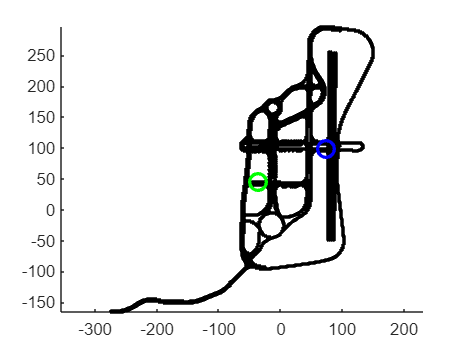

%print section
figure
hold on
for i =1:numel(lanes)
    control_points = lanes(i).geometry.values;
    x_coords = arrayfun(@(cp) cp.x,control_points);
    y_coords = arrayfun(@(cp) cp.y,control_points);
    plot(x_coords,y_coords, 'k.-');
end
% Plot start position in green
plot(xpointstart, ypointstart, 'go', 'MarkerSize', 10, 'LineWidth', 2);

% Plot end position in red
plot(xpointgoal, ypointgoal, 'bo', 'MarkerSize', 10, 'LineWidth', 2);

hold off
axis equal

egoStart = strjoin(string(start),",");
setScenarioVariable(rrApp,"EgoInitialPosition",egoStart);
egoStartPosition = getScenarioVariable(rrApp,"EgoInitialPosition");
egoStartPosition = str2double(split(egoStartPosition,","))';

egoGoal = strjoin(string(goal),",");
setScenarioVariable(rrApp,"Goal",egoGoal);
egoGoalPosition = getScenarioVariable(rrApp,"Goal");
egoGoalPosition = str2double(split(egoGoalPosition,","))';
setScenarioVariable(rrApp,EgoGoalPosition=['[',num2str(egoGoalPosition),']']);

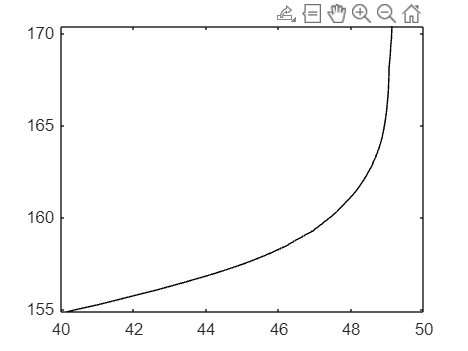

planner = plannerAStar(graph);
%refPath = HelperPlanPath.planPath(planner,graph,egoStartPosition,egoGoalPosition);
refPath = HelperPlanPath.planPath(planner,graph,start,goal);

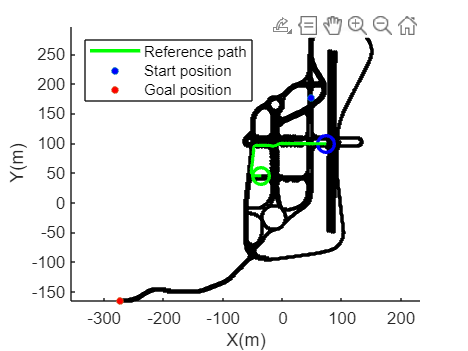

pRefPath = plot(refPath(:,1),refPath(:,2),Color="g",LineWidth=2);
% Plot markers for start and goal positions
pStart = plot(egoStartPosition(1),egoStartPosition(2),"o",MarkerFaceColor="b",MarkerSize=4);
pEnd = plot(egoGoalPosition(1),egoGoalPosition(2),"o",MarkerFaceColor="r",MarkerSize=4);
% Add legends
legend([pRefPath pStart pEnd],{"Reference path","Start position","Goal position"},Location="northwest")

set(rrSim,SimulationCommand="Start")
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(0.01)
end

setScenarioVariable(rrApp,ChangeSpeed_TargetSpeed="18")

obstacleDistance = 50;
setScenarioVariable(rrApp,ReplanTriggerDistance=num2str(obstacleDistance));
setScenarioVariable(rrApp,ObstacleDistance=num2str(obstacleDistance));